# JCNS Fig2

# Recurrent Network; Ring network; Spike added to V

Note!! Don't run simulation section on the laptop - see the HPC scripts.

## Setups

CurrentFolder = pwd;
addpath([CurrentFolder '/Utils'])

T = 1000;
%dt1 = 0.05; dt2 = dt1/2;

N = 600;NE = 300;NI= 300;
V_0s = rand(N,1);
lambda = 0.55;
%tau = 5;

% I_0 = lambda*f*tau;
fs = [0.07*ones(NE,1);0.07*ones(NI,1)];
% see = 0.007;sei = 0.007;
% sie=0.007;   sii=0.007;

% pp = 1;
% pE = pp; pI = pp;
% SE = 1*((rand(N,NE))<pE);
% SI = 1*((rand(N,NI))<pI);
% S = [SE,SI];
NeighborScale = 5; % 60 30 10 5
%Neighbor 5  10 30 60
N_conn = floor(NE/NeighborScale);
S_SWconn = zeros(NE);
for postInd = 1:NE
    for preInd = 1:NE
        if mod(postInd-preInd,NE)<=N_conn/2 | mod(postInd-preInd,NE)>= NE-N_conn/2
            S_SWconn(postInd,preInd) = 1;
        end
    end
end
S = repmat(S_SWconn,2,2);

for jj = 1:N
    S(jj,jj)=0;
end

ss1 = 0.003;%*NE/N_conn;
ss2 = 0.003;%*NE/(N_conn);


N_Sample = 32;
dtAll = [0.1,0.05];
SharedFacNum = 11;
SharedProp = linspace(0,1,SharedFacNum);

## 10 SharedProp; Each include 50 pairs of coupled simulations 

Vs    = cell(N_Sample,SharedFacNum,2);
spike = cell(N_Sample,SharedFacNum,2);
SpikeCount = cell(N_Sample,SharedFacNum,2);
t     = cell(N_Sample,SharedFacNum,2);
spiketime  = cell(N_Sample,SharedFacNum,2);

for ShareInd = 1:SharedFacNum
    ShareFactor = SharedProp(ShareInd);
    Nevent    = floor(T*lambda*2);
    NSHAEvent = floor(ShareFactor*Nevent); % number of shared input
    NIIDEvent = Nevent - NSHAEvent;        % number of iid events
    
    tic
    for SamInd = 1:N_Sample
        % Make up input event by mixing shared input and iid input
        eventsN = zeros(N,Nevent);
        SharedEvent = Poisson_Process_2(lambda*ShareFactor,T);
        for ii = 1:N
            IIDevent = Poisson_Process_2(lambda*(1-ShareFactor),T);
            FinalEvent = sort([SharedEvent;IIDevent]);
            eventsN(ii,1:length(FinalEvent)) = FinalEvent';
        end
        
        for dtInd = 1:length(dtAll)
            dt = dtAll(dtInd);
            
            [Vs{ShareInd, SamInd, dtInd},spike{ShareInd, SamInd, dtInd},...
                t{ShareInd, SamInd, dtInd}, SpikeCount{ShareInd, SamInd, dtInd},~,~] = ...
                MC_Vseries_for_network_ninput_I_based_norms_Syn(dt,T,V_0s,eventsN,fs,S,ss1,ss2,ss2,ss1,NE,NI);
            
            [Sp_n,Sp_t] = find(spike{ShareInd, SamInd, dtInd} == 1);
            spiketime{ShareInd, SamInd, dtInd} = (Sp_t-1)*dt;
        end
        
    end
    toc
end

## Plot optimal ratio

addpath([CurrentFolder '/HPCData/Figure2 IndPaths Samples'])
addpath([CurrentFolder '/HPCData'])
OptR2 = zeros(SharedFacNum,N_Sample); % optimal var ratio
SEAll = zeros(SharedFacNum,N,497); % side entropy
SEShow = zeros(SharedFacNum,2); % Mean and std

FrShow = zeros(SharedFacNum,2); % Mean and std
for ShareInd = 1:SharedFacNum
    ShareFactor = SharedProp(ShareInd)
    tic
    FrRecord = zeros(1,N_Sample);
    for SamInd = 1:N_Sample
        load(sprintf('fig2JCNS_ShF%.1f_Sam%d.mat', ShareFactor, SamInd),'spike','SpikeCount');
        SpDiff = sum(SpikeCount{1} - SpikeCount{1+1});
        SpSum = sum(SpikeCount{1+1});
        r2 = var(SpDiff(:),'omitnan')/var(SpSum(:),'omitnan'); % Variance ratio: Diff/V2
        %         load(sprintf('fig2JCNS_ShF%.1f_Sam%d.mat', ShareFactor, SamInd),'Vs');
        %         VDiff = Vs{1} - Vs{2}(:,1:2:end);
        %
        %         r2 = var(sum(VDiff),'omitnan')/var(sum(Vs{2}),'omitnan'); % Variance ratio: Diff/V2
        
        % allSpDiff = sum(abs(SpDiff(:)))
        rho = sqrt(r2)/sqrt(3); % optimal sample ratio
        OptR2(ShareInd,SamInd) = 1/2 + 3/2*rho + r2*(1/(2*rho)+3/2); % optimal var reduction ratio
        
        FrEventsN = sum(spike{1},'all');
        FrRecord(SamInd) = FrEventsN;
    end
    FrShow(ShareInd,1) = mean(FrRecord/(T/1000)/N);
    FrShow(ShareInd,2) = std(FrRecord/(T/1000)/N);
%     % Now go to cosine similarity. NOTE!! CS does not work well!!
%     SpikeCountAll = zeros(N_Sample,size(SpikeCount{2},1),size(SpikeCount{2},2));
%     for SamInd = 1:N_Sample
%         load(sprintf('fig2JCNS_ShF%.1f_Sam%d_SameInp.mat', ShareFactor, SamInd),'SpikeCount');
%         SpikeCountAll(SamInd,:,:) =  SpikeCount{2};
%     end
%     % Use Side Entropy instead
%     for NeuInd = 1:N
%         for TWinInd = 1:size(SpikeCountAll,3)
%             FrCountDistb = SpikeCountAll(:,NeuInd,TWinInd);
%             [uPhase,~,ic] = unique(FrCountDistb);
%             Ptally = accumarray(ic, 1)/N_Sample + 1e-32; % add a small probability to avoid nan
%             SEAll(ShareInd,NeuInd,TWinInd) = -sum(Ptally.*log2(Ptally));
%         end
%     end
%     
%     SWNow = squeeze(SEAll(ShareInd,:,:));
%     SWNow(:,1:100) = [];
%     SEShow(ShareInd,1) = mean(SWNow(:),'omitnan');
%     SEShow(ShareInd,2) = std(SWNow(:),'omitnan');
    toc
end

ShareFactor = 0

历时 2.606245 秒。


ShareFactor = 0.1000

历时 2.709682 秒。


ShareFactor = 0.2000

历时 3.237934 秒。


ShareFactor = 0.3000

历时 3.901208 秒。


ShareFactor = 0.4000

历时 3.384849 秒。


ShareFactor = 0.5000

历时 3.231675 秒。


ShareFactor = 0.6000

历时 3.230684 秒。


ShareFactor = 0.7000

历时 3.134290 秒。


ShareFactor = 0.8000

历时 3.020466 秒。


ShareFactor = 0.9000

历时 3.015170 秒。


ShareFactor = 1

历时 3.307543 秒。


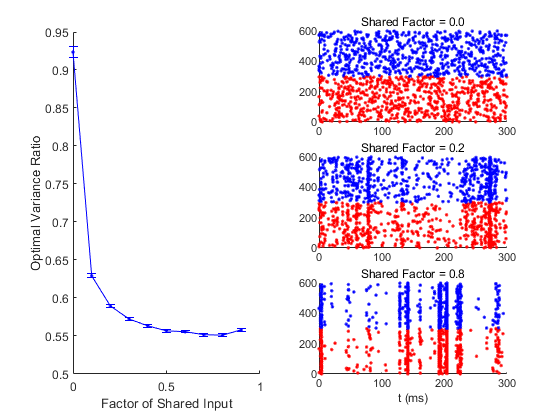


figure('Name','Fig2')
subplot 121
hold on
plot(SharedProp,mean(OptR2,2),'b-')
errorbar(SharedProp,mean(OptR2,2),std(OptR2,[],2)/sqrt(N_Sample),'b.')
% yyaxis right
% plot(SharedProp,mean(RDAll,2),'g-')
% errorbar(SharedProp,mean(RDAll,2),std(RDAll,[],2),'g.')
xlabel('Factor of Shared Input')
ylabel('Optimal Variance Ratio')
%ylim([0 0.03])

SamIndShow  = [1,3,9];
for SamIndShowInd = 1:length(SamIndShow)
    subplot(3,2,2*SamIndShowInd)
    ShareFactor = SharedProp(SamIndShow(SamIndShowInd));
    SamInd = 1;
    
    load(sprintf('fig2JCNS_ShF%.1f_Sam%d.mat', ShareFactor, SamInd), 'spike');
    [NeuInds,TInd] = find(spike{2}>0);
    hold on
    scatter(TInd(NeuInds<=NE)*dtAll(2),NeuInds(NeuInds<=NE), 'r.')
    scatter(TInd(NeuInds>NE)*dtAll(2), NeuInds(NeuInds>NE),  'b.')
    hold off
    title(sprintf('Shared Factor = %.1f',ShareFactor))
    xlim([0 300])
end
subplot 326
xlabel('t (ms)')